# Matlab Project Assignment

# The Final MATLAB Project

## 1. Q1 

## Q2 & Q3

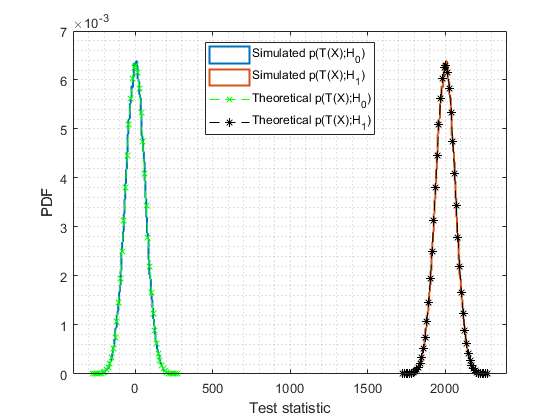

close all ; clear ; clc ;
rng(0) ; % reset the random number generator (for reproducibility)
% format long eng

%%%%%%%% Q2

MC = 100000 ; % number of Monte Carlo loops
A = sqrt(20) ;
sigma_squared = 2 ; % Noise variance
N = 100 ; % Number of samples in the data



S = ones(N,1) ;
% P_S = S'*S/N  % to check the power of S


%%% Generating of the samples
noise = randn(N,MC)*sqrt(sigma_squared) ; % W ==> N columns of WGN repeated MC rows
D = A*S ; % the signal to be detected
% var(noise,1)
X_no_signal = noise ;
X_with_signal = D + noise ;

%%% Calculating the test statistics
T_H0 = D'*X_no_signal ; % test statistics when there's no signal (i.e H0)
T_H1 = D'*X_with_signal ; %test statistics when there's a signal (i.e H1)

% means = [mean(T_H0)  mean(T_H1)] 
% varainces = [var(T_H0) var(T_H1) ] 

B0 = histogram(T_H0,'Normalization','pdf','DisplayStyle','stairs','LineWidth',1.5);
hold on
B1 = histogram(T_H1,'Normalization','pdf','DisplayStyle','stairs','LineWidth',1.5);

E_D = D'*D ; % energy of D=A*S

% pdf ranges on x axis ie T(X) range
x_H0 = linspace(B0.BinLimits(1),B0.BinLimits(2),50) ;
x_H1 = linspace(B1.BinLimits(1),B1.BinLimits(2),50) ;
% x_H1 = linspace(000,800,100) ; % for bugs

T_H0_theory = normpdf(x_H0,0, sqrt(E_D*sigma_squared)) ;
T_H1_theory = normpdf(x_H1,E_D, sqrt(E_D*sigma_squared)) ;

% E_D
% means = [mean(T_H0_theory)  mean(T_H1_theory)] 
% varainces = [var(T_H0_theory) var(T_H1_theory) ] 

plot(x_H0,T_H0_theory,'gx--',x_H1,T_H1_theory,'k*--')

grid minor
legend('Simulated p(T(X);H_{0})','Simulated p(T(X);H_{1})','Theoretical p(T(X);H_{0})','Theoretical p(T(X);H_{1})',Location='north')
xlabel('Test statistic'); ylabel('PDF')
hold off

exportgraphics(gcf,'Q2_plot.pdf')




%%%%%%%% Q3

ENR = E_D/sigma_squared ; % Energy to noise Ratio


%%% 1st approach (gives a step)
% P_FA = linspace(0,1,1000) ;
% P_D = qfunc(qfuncinv(P_FA)-sqrt(ENR)) ;

%%% 2nd approach (gives a more insight)
gamma_p = -MC/2:0.01:+MC/2 ;
P_FA = qfunc(gamma_p./sqrt(sigma_squared*E_D)) ;
P_D = qfunc(qfuncinv(P_FA)-sqrt(ENR)) ;

figure
loglog(P_FA,P_D)

grid minor
xlabel('P_{FA}'); ylabel('P_{D}')

exportgraphics(gcf,'Q3_plot.pdf')

## Q4

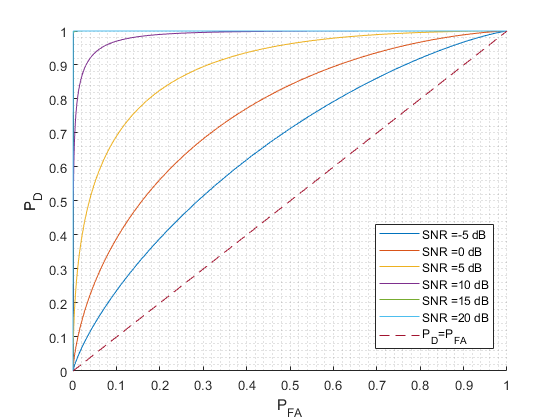

close all ; clear ; clc ;
% format long eng

MC = 100000 ; % number of Monte Carlo loops
sigma_squared = 2 ; % Noise variance
N = 100 ; % Number of samples in the data

SNR_dB = [-5 0 5 10 15 20] ;
SNR = 10.^(SNR_dB/10) ;
A = sigma_squared*SNR/N ;
E_D = N*A.^2 ; % energy of D=A*S

figure
hold on

gamma_p = (-MC:0.01:+MC) ;
for ii = 1:length(SNR)
    P_FA = qfunc(gamma_p./sqrt(sigma_squared*E_D(ii))) ;
    P_D = qfunc(qfuncinv(P_FA)-sqrt(SNR(ii))) ;
    
    loglog(P_FA,P_D) 
    
    myLegend{ii} = strcat('SNR =', num2str(SNR_dB(ii)), ' dB') ; 
end

x_limit = 0:0.01:1 ;
plot(x_limit,x_limit,'--')
myLegend{end+1} = 'P_{D}=P_{FA}' ;
legend(myLegend,'Location','best')
grid minor
xlabel('P_{FA}'); ylabel('P_{D}')
hold off

exportgraphics(gcf,'Q4_plot.pdf')

## Q5

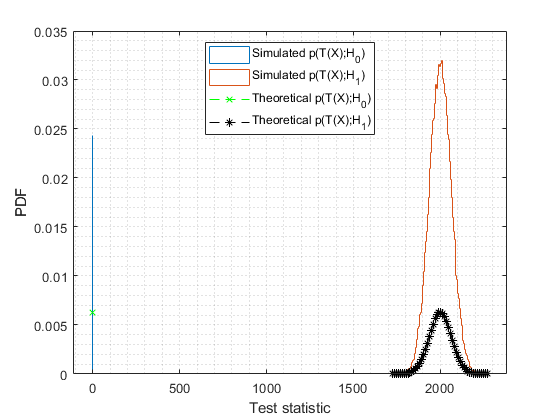

close all ; clear ; clc ;
rng(0) ; % reset the random number generator (for reproducibility)
% format long eng

%%%%%%%% Q2

MC = 100000 ; % number of Monte Carlo loops
A = sqrt(20) ;
sigma_squared = 2 ; % Noise variance
N = 100 ; % Number of samples in the data



S = ones(N,1) ;
% P_S = S'*S/N  % to check the power of S


%%% Generating of the samples
noise = randn(N,MC)*sqrt(sigma_squared) ; % W ==> N columns of WGN repeated MC rows
D = A*S ; % the signal to be detected
% var(noise,1)
X_no_signal = noise ;
X_with_signal = D + noise ;

%%% Estimating A 
A_estimated_H0 = mean(X_no_signal,'all') ;
A_estimated_H1 = mean(X_with_signal,'all') ;

%%% Calculating the test statistics
T_H0 = A_estimated_H0*S'*X_no_signal ; % test statistics when there's no signal (i.e H0)
T_H1 = A_estimated_H1*S'*X_with_signal ; %test statistics when there's a signal (i.e H1)

% means = [mean(T_H0)  mean(T_H1)] 
% varainces = [var(T_H0) var(T_H1) ] 

B0 = histogram(T_H0,'Normalization','probability','DisplayStyle',"stairs");
hold on
B1 = histogram(T_H1,'Normalization','probability','DisplayStyle',"stairs");

% E_D = D'*D ; % energy of D=A*S
E_D = N*A.^2 ; % energy of D=A*S

% pdf ranges on x axis ie T(X) range
x_H0 = linspace(B0.BinLimits(1),B0.BinLimits(2),50) ;
x_H1 = linspace(B1.BinLimits(1),B1.BinLimits(2),50) ;
% x_H1 = linspace(000,800,100) ; % for bugs

T_H0_theory = normpdf(x_H0,0, sqrt(E_D*sigma_squared)) ;
T_H1_theory = normpdf(x_H1,E_D, sqrt(E_D*sigma_squared)) ;

% E_D
% means = [mean(T_H0_theory)  mean(T_H1_theory)] 
% varainces = [var(T_H0_theory) var(T_H1_theory) ] 

plot(x_H0,T_H0_theory,'gx--',x_H1,T_H1_theory,'k*--')

grid minor
legend('Simulated p(T(X);H_{0})','Simulated p(T(X);H_{1})','Theoretical p(T(X);H_{0})','Theoretical p(T(X);H_{1})',Location='north')
xlabel('Test statistic'); ylabel('PDF')
hold off

exportgraphics(gcf,'Q5_plot.pdf')